# Example: Streaming video in external mode

This example will show you how to show the video feed from the AR Drone 2.0 within Simulink using External mode. 

## Displaying video in External mode

There are many different ways to display video in Simulink using various Simulink Video Display blocks for different target hardware platforms. The AR Drone 2.0 however does not support direct video output meaning that any code compiled for the AR Drone 2.0 can not assume the drone is capable of displaying video. This example contains an implementation which is capable of streaming video from the drone to Simulink in external mode which you can open via:

open('AR_Drone_Models\Example_Models\Example_Streaming_Video_In_External_Mode.slx');

 This command will open the following Simulink model:

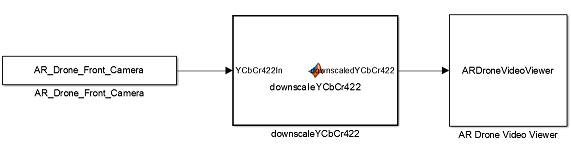

The AR_Drone_Front_Camera block on the left is created using the Legacy Code Tool using the C code in video.c. It contains initialization, step and termination functions for both the front and bottom camera. You can see how the video signal is retrieved exactly by evaluating:

edit('video.c');

The videoInit1 and videoInit2 functions query the AR Drone's front and bottom camera for video capture respectively. 

- The correct camera parameters are set and memory is allocated to use as an image buffer. 

- The videoGrabImage1 and videoGrabImage2 functions are used to retrieve a new frame from the AR Drone's video channel and memory copy it to an array. This array is accessed as the block output via a pointer. 

- The videoClose1 and videoClose2 functions free up the memory which was allocted during initialization. 

As this example uses the AR_Drone_Front_Camera block, only the videoInit1, videoGrabImage1 and videoClose1 functions are actually used. 

As the drone runs in external mode the amount of bandwith necessary for the video stream should be limited to ensure sufficient bandwidth remains for external mode connectivity. The second block in the model, "downscaleYCbCr422" is responsible for limiting the bandwith by taking the original input images (Which use the YCbCr color space and 4:2:2 pixel subsampling) and down sampling by a user specified amount (in both horizontal and vertical direction). Taking the original 1280*720 image and down sampling 8 times results in a video stream of 160x90 pixels, a reduction in bandwidth of 98.44%. Another way in wich the bandwidth is limited is by reducting the sampling time of "AR_Drone_Front_Camera" to 10 Fps. Sending too much data will cause the model to be unable to receive any shutdown packets from Simulink meaning the AR Drone 2.0 needs to be reset by unplugging the battery.

The ARDroneVideoViewer block is what enables the video stream to be displayed in Simulink. It is a level-2 MATLAB S-Function which has been configured to work as a Sim Viewing Device. This causes Embedded Coder to ignore all code within the ARDroneVideoViewer S-Function when compiling for the AR Drone 2.0 target and run it on your Simulink PC instead. The signal which goes into the ARDroneVideoViewer is sent to Simulink using external mode. The transformation from YCbCr422 to RGB is then done on the Simulink PC to ease the computational burden on the drone. Displaying the video feed is simply done by giving the RGB image to the MATLAB function 'image' within the S-Function.

## Viewing the bottom camera:

A second model is available to view the video feed from the bottom facing camera on the AR Drone 2.0. This camera can output video with a resolution of 320x240 at 50 fps. A lower Fps is used and down sampling is once again implemented to reduce the needed TCP/IP bandwidth. To open this second model evaluate the following MATLAB command:

open('AR_Drone_Models\Example_Models\Example_Streaming_Bottom_Video_In_External_Mode.slx');

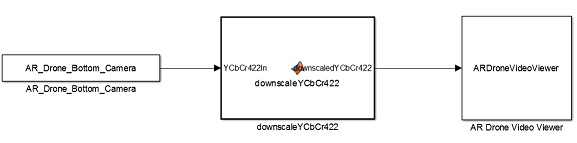

The bottom camera uses a different aspect ratio (4:3) than the front camera (16:9) which is entered in the ARDroneVideoViewer block parameters diaglog box. Running the model will open a figure showing the bottom camera video feed. In the commercial application of the AR Drone 2.0 software the bottom camera is used to have a form of global positioning. If the floor beneath the drone has clearly distinguishable features/patterns the drone will be able to compensate for drift which it would otherwise not be able to detect using other sensors.